# Lab 4

clear;
warning("off");

## Experiment 1

Experimental Procedure:

For each of our MOSFETs on the ALD1106 we shorted their drains and gates together, attaching the SMU's Vdd to pin 11, and attaching the SMU's ground to pin 4. For each MOSFET, we applied a range of currents (10 nano amps to 1 milli amp) to the drain source connections using Ch1 and measured the voltage using Ch1.

Ut = 0.025;
load("exp1_1_new.mat")

voltage1 = Diode_Voltage;
current1 = ch1;
[Is1, VT1, k1] = ekvfit(voltage1, current1, 0.0005);

load("exp1_2_new.mat")

voltage2 = Diode_Voltage;
current2 = ch1;
[Is2, VT2, k2] = ekvfit(voltage2, current2, 0.0005);

load("exp1_3_new.mat")

voltage3 = Diode_Voltage;
current3 = ch1;
[Is3, VT3, k3] = ekvfit(voltage3, current3, 0.0005);
load("exp1_4_new.mat")

voltage4 = Diode_Voltage;
current4 = ch1;
[Is4, VT4, k4] = ekvfit(voltage4, current4, 0.0005);
clf
figure(1)

[Is, VT, k] = ekvfit(voltage3, current3, 0.0005);
compute_current = @(voltage) Is .* log(1 + exp((k*(voltage-VT))/(2*Ut))).^2;
theoretical_current1 = compute_current(voltage3);
transistors = ["First Transistor";"Second Transistor";"Third Transistor"; "Fourth Transistor"];
k_vals = [k1; k2; k3; k4];
VT_vals = [VT1; VT2; VT3; VT4];
Is_vals = [Is1; Is2; Is3; Is4];
Diode_Values = table(transistors, k_vals, VT_vals, Is_vals, 'VariableNames', ["Transistors", " Reciprocal Subthreshold Slope Factor", "Zero-Bias Threshold Voltage (Volts)","Specific current (Amps)"])

Diode_Values = 4×4 table
        Transistors         Reciprocal Subthreshold Slope Factor    Zero-Bias Threshold Voltage (Volts)    Specific current (Amps)
    ___________________    _____________________________________    ___________________________________    _______________________

    "First Transistor"                    0.74087                                 0.57532                        1.5991e-06       
    "Second Transistor"                   0.76822                                 0.57192                        1.4648e-06       
    "Third Transistor"                    0.74156                                 0.57502                        1.5709e-06       
    "Fourth Transistor"                   0.70816                                 0.57713                        1.7346e-06       


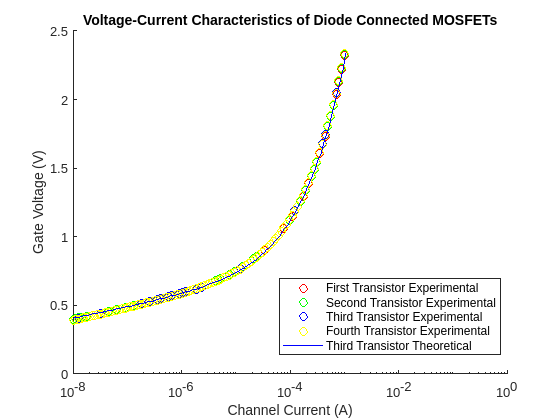

hold on 
title("Voltage-Current Characteristics of Diode Connected MOSFETs")
ylabel("Gate Voltage (V)")
xlabel("Channel Current (A)")
plot(current1,voltage1, 'ro','DisplayName',"First Transistor Experimental")
plot(current2,voltage2, 'go','DisplayName',"Second Transistor Experimental")
plot(current3,voltage3, 'bo','DisplayName',"Third Transistor Experimental")
plot(current4,voltage4, 'yo','DisplayName',"Fourth Transistor Experimental")
plot(theoretical_current1, voltage3, 'b-','DisplayName',"Third Transistor Theoretical")
set(gca, "XScale", "log");
xlim([10^-8, 1])
legend('show', 'Location', 'best');
hold off

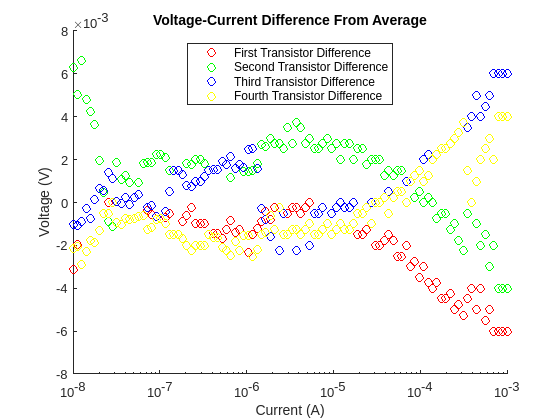

mean = (flip(voltage1) + flip(voltage2) + flip(voltage3) + flip(voltage4))/4;

clf;
figure(2)
hold on
title("Voltage-Current Difference From Average")
ylabel("Voltage (V)")
xlabel("Current (A)")
plot(flip(current1), flip(voltage1) - mean, 'ro','DisplayName',"First Transistor Difference")
plot(flip(current2), flip(voltage2) - mean, 'go','DisplayName',"Second Transistor Difference")
plot(flip(current3), flip(voltage3) - mean, 'bo','DisplayName',"Third Transistor Difference")
plot(flip(current4), flip(voltage4) - mean, 'yo','DisplayName',"Fourth Transistor Difference")
set(gca, "XScale", "log");
legend('show', 'Location', 'best');
hold off

The voltage current characteristic matches very well across weak, moderate and strong inversion as they do not deviate more than 7 milliovolts from the average. However, the most variation from the average is seen during strong inversion, meaning that is when they match the worst. They match relatively well during weak and moderate inversion. 

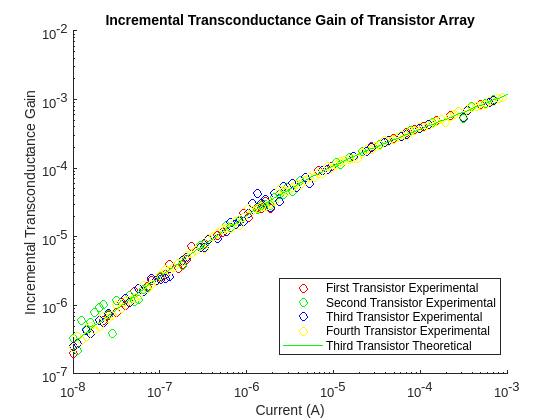

compute_gm = @(current, Is, k) k.*(sqrt(Is .* current)./Ut) .* (1-exp(-sqrt(current./Is)));

exp1_gm = diff(current1)./diff(voltage1);
exp2_gm = diff(current2)./diff(voltage2);
exp3_gm = diff(current3)./diff(voltage3);
exp4_gm = diff(current4)./diff(voltage4);

theo3_gm = compute_gm(current3, Is , k);
clf;
figure(7);
hold on
title("Incremental Transconductance Gain of Transistor Array")
ylabel("Incremental Transconductance Gain")
xlabel("Current (A)")
plot(current1(2:end), exp1_gm, 'ro','DisplayName',"First Transistor Experimental")
plot(current2(2:end), exp2_gm, 'go','DisplayName',"Second Transistor Experimental")
plot(current3(2:end), exp3_gm, 'bo','DisplayName',"Third Transistor Experimental")
plot(current4(2:end), exp4_gm, 'yo','DisplayName',"Fourth Transistor Experimental")
plot(current3, theo3_gm, 'g-','DisplayName',"Third Transistor Theoretical");
legend('show', 'Location', 'best');
set(gca, "XScale", "log");
set(gca, "YScale", "log");
hold off

The theoretical fit matches very well with the experimental data.

## Experiment 2

Experimental Procedure:

We setup two of our MOSFETs in the ALD1106 in a current mirror configuration by shorting their gates together along with shorting the source of one MOSFET to the two gates, attaching the SMU's Vdd to pin 11, and attaching the SMU's ground to pin 4. We applied 5 volts to the mirror MOSFET's source using Ch2 and applied a range of currents (10 nano amps and 1 milli amp) to the source gate connection using Ch1 while measuring voltage using Ch1.

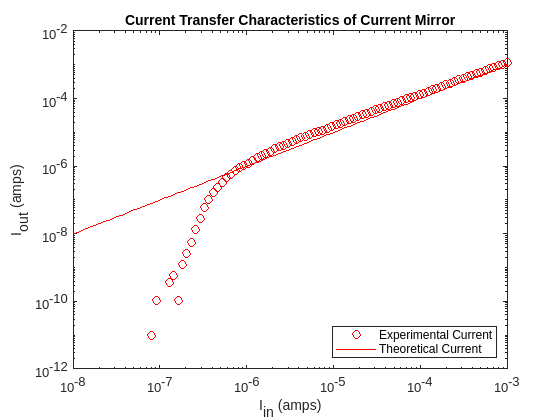

clear;
clf;
load("Ex_2_1.mat");
theo_fit = ch1;
figure(3);
loglog(ch1, MDiode_Current, 'ro');
hold on
loglog(ch1, theo_fit, 'r-');
title("Current Transfer Characteristics of Current Mirror");
xlabel("I_i_n (amps)");
ylabel("I_o_u_t (amps)")
legend("Experimental Current", "Theoretical Current", "location", "southeast");
hold off

The mirroring MOSFET should theoretically match the first MOSFET's current which it does past 10^(-6) amps. When the input current is less than 10^(-6) amps,

the experimental current doesn't match the theoretical current well.

## Experiment 3

Experimental Procedure

We setup two of our MOSFETs in the ALD1106 in a current mirror configuration by shorting their gates together along with shorting the source of one MOSFET to the two gates, attaching the SMU's Vdd to pin 11, and attaching the SMU's ground to pin 4. We ran three experiments, where we changed I_in (100 nano amps, 1 micro amp, and 100 micro amps) using Ch1 to measure the different levels of inversion while supplying a range of voltages (0-2 volts) to the mirror MOSFET's source using Ch2 while measuring the current through the mirror MOSFET's channel using Ch2.

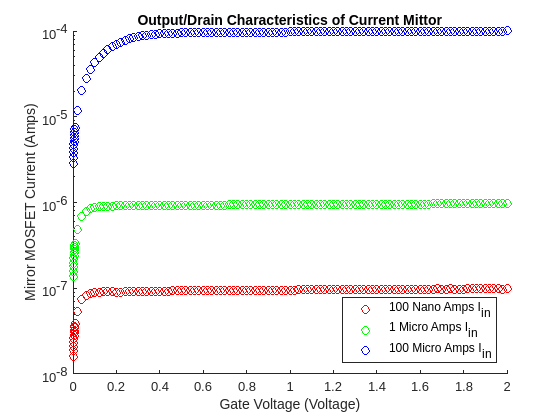

clear;
clf;
load("Ex_3_100nano.mat");
nano_100_voltage = ch2_voltage;
nano_100_current = mos_current;
load("Ex_3_1micro.mat");
micro_1_voltage = ch2_voltage;
micro_1_current = mos_current;
load("Ex_3_100micro.mat")
micro_100_voltage = ch2_voltage;
micro_100_current = mos_current;

figure();
hold on
plot(nano_100_voltage, nano_100_current, 'ro');
plot(micro_1_voltage, micro_1_current, 'go');
plot(micro_100_voltage, micro_100_current, 'bo');
title("Output/Drain Characteristics of Current Mittor")
xlabel("Gate Voltage (Voltage)");
ylabel("Mirror MOSFET Current (Amps)");
set(gca, "YScale", "log");
xlim([0 2])
legend("100 Nano Amps I_i_n", "1 Micro Amps I_i_n", "100 Micro Amps I_i_n", "location", "southeast")
hold off

I_in_Current = ["100 Nano Amps";"1 Micro Amps";"100 Micro Amps"];
I_in = [1e-7; 1e-6; 1e-4];
Early_Voltage = [26.32; 30.855; 29.938];
Saturation_Current = [9.16e-8; 9.14e-7; 9.16e-5];
Early_Effect_Resistance = Early_Voltage./Saturation_Current;
Transistor_On_Resistance = 1./Early_Effect_Resistance;
Intrinsic_Gain = Early_Effect_Resistance./Transistor_On_Resistance;
MOS_properties = table(I_in_Current, Early_Voltage, Early_Effect_Resistance, Transistor_On_Resistance, Intrinsic_Gain, 'VariableNames', ["I_in Current (Amps)", "Early Voltage (Volts)","Early Effect Resistance (Ohms)","Transistor On Resistance (Ohms)","Intrinsic Gain"])

MOS_properties = 3×5 table
    I_in Current (Amps)    Early Voltage (Volts)    Early Effect Resistance (Ohms)    Transistor On Resistance (Ohms)    Intrinsic Gain
    ___________________    _____________________    ______________________________    _______________________________    ______________

     "100 Nano Amps"               26.32                      2.8734e+08                        3.4802e-09                 8.2562e+16  
     "1 Micro Amps"               30.855                      3.3758e+07                        2.9622e-08                 1.1396e+15  
     "100 Micro Amps"             29.938                      3.2683e+05                        3.0597e-06                 1.0682e+11  


The approximations based on the assumptions that the intrinsic gain is greater than unity is a good one because the intrinsic gain is significantly greater than 1 in all 3 types of inversion. Across inversion levels, this assumption is generally a good one.